# Ordinary Differential Equations

## Introduction

### Definition of a Differential Equation			

A *differential equation is *an equation involving derivatives or differentials. The following are some examples of differential equations.

        **Example 1.** $(y\prime\prime)^2+3x=2(y\prime)^3$ where $y\prime=\frac{\mathrm dy}{\mathrm dx}$, $y\prime\prime=\frac{\mathrm d^2y}{\mathrm dx^2}$

        **Example 2.** $\frac{\mathrm dy}{\mathrm dx}+\frac{y}{x}=y^2$

        **Example 3.** $\frac{\mathrm d^2Q}{\mathrm dt^2}-3\frac{\mathrm dQ}{\mathrm dt}+2Q=4\sin2t$ or $\ddot Q-3\dot Q+2Q=4\sin2t$

        **Example 4. **$\frac{\mathrm dy}{\mathrm dx}=\frac{x+y}{x-y}$ or $(x+y)\mathrm dx+(y-x)\mathrm dy=0$

        **Example 5.** $\frac{\partial^2V}{\partial x^2}+\frac{\partial^2V}{\partial y^2}=0$

Equations such as those in Examples 1-4 involving only one independent variable are called *ordinary differential equations. *Equations such as that of Example 5 with two or more independent variables are called *partial differential equations *and are treated in Lecture 03.

### Order of a Differential Equation

An equation having a derivative of $n$th order but no higher is called an $n$th *order differential equation. *In Examples 1-5 above, the orders of the differential equations are 2,1, 2,1, 2, respectively.

### Arbitrary Constants

An arbitrary constant, often denoted by a letter at the beginning of the alphabet such as $A$*, *$B$*, *$C$*, *$c_1$, $c_2$, etc., may assume values independently of the variables involved. For example in $y= x^2+c_1 x+c_2$, $c_1$ and $c_2$ are arbitrary constants. 

The relation $y = A\mathrm e^{-4x +B}$ which can be written $y = A\mathrm e^B\mathrm e^{-4x}=C\mathrm e^{-4x}$ actually involves only one arbitrary constant. We shall always assume that the minimum number of constants is present, i.e. the arbitrary constants are *essential. *

### Solution of Differential Equation

A *solution *of a differential equation is a relation between the variables which is free of derivatives and which satisfies the differential equation identically.

        **Example 6.** $y=x^2+c_1x+c_2$ is a solution of $y\prime\prime =2$ since by substitution we obtain the identity $2=2$

clear
syms x c1 c2
y = x^2 + c1*x + c2;
diff(y, x, 2)

$$ans = 2$$

A *general solution* of an $n$th order differential equation is one involving $n$ (essential) arbitrary constants.

        **Example 7.** Since $y=x^2+c_1x+c_2$ has two arbitrary constants and satifies the second order differential equation $y\prime\prime =2\,,$ it is a general solution of $y\prime\prime =2$.  

*A particular solution *is a solution obtained from the general solution by assigning specific values to the arbitrary constants. 

        **Example 8.** Since $y=x^2-3x+2$ is a particular solution of $y\prime\prime =2$, and is obtained from the general solution $y=x^2+c_1x+c_2$ by putting $c_1=-3$ and $c_2=2$.

y = subs(y, [c1, c2], [-3, 2])

$$y = x^{2}-3\,x+2$$

A *singular solution *is a solution which cannot be obtained from the general solution by specifying values of the arbitrary constants. 					

        **Example 9.** The general solution of $y=xy\prime-y\prime^2$ is $y=cx-c^2$*. *However, as seen by substitution another solution is $y=\frac{x^2}{4}$ which cannot be obtained from the general solution for any constant $c$. This second solution is a singular solution.

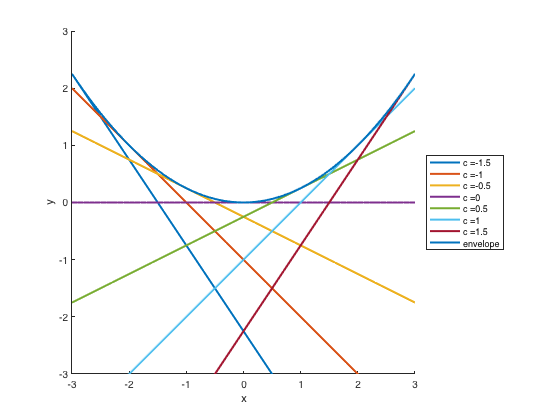

clear
figure
x = -3:0.1:3;
y = x.^2/4;
hold on
legends = {};
for c = -1.5:0.5:1.5
    plot(x, c*x-c^2, 'LineWidth', 2)
    legends{end+1} = strcat('c = ', num2str(c));
end
plot(x,y,'LineWidth',2); xlabel('x'); ylabel('y')
legends{end+1} = 'envelope';
legend(legends, 'Location', 'eastoutside')
axis equal
axis([-3 3 -3 3])

It is seen that $y=cx-c^2$ represents a family of straight lines tangent to the parabola $y=\frac{x^2}{4}$*. *The parabola is the *envelope *of the family of straight lines.

The envelope of a family of curves $G(x, y, c)=0$, if it exists, can be found by solving simultaneously the equations $\frac{\partial G}{\partial c} = 0$ and $G=0$. In this example $G(x,y, c) = y-cx+c^2$ and $\frac{\partial G}{\partial c} = -x+2c$. Solving simultaneously $-x+2c=0$ and $y-cx+c^2=0$, we find $x=2c$*, *$y=c^2$ or $y=\frac{x^2}{4}$*.*

clear
syms x y c
G = y-c*x+c^2;
[xs, ys] = solve(G==0, diff(G, c)==0, x, y)

$$xs = 2\,c$$

$$ys = c^{2}$$

subs(ys, c, solve(x==xs, c))

$$ans = \frac{x^{2}}{4}$$

### Differential Equation of a Family of Curves

A general solution of an $n$th order differential equation has $n$ arbitrary constants (or parameters) and represents geometrically an $n$* parameter family of curves. *Conversely a relation with $n$ arbitrary constants [sometimes called a *primitive] *has associated with it a differential equation of order $n$ [of which it is a general solution] called the *differential equation of the family. *This differential equation is obtained by differentiating the primitive $n$ times and then eliminating the $n$ arbitrary constants among the $n + 1$ resulting equations.

        **Example 10.** Obtain the differential equation for the one parameter family of curves $y=cx^3$.

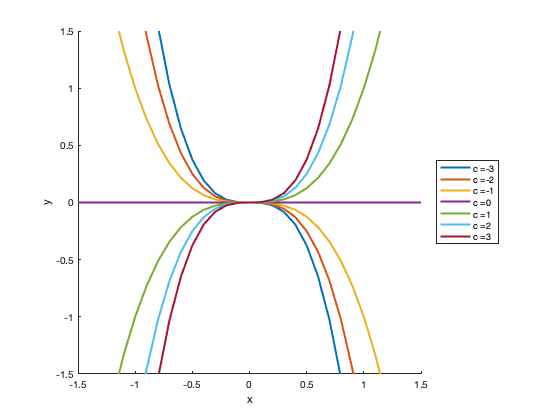

clear
figure
x = -1.5:0.1:1.5;
xlabel('x'); ylabel('y'); hold on
legends = {};
for c = -3:3
    plot(x, c*x.^3,'LineWidth',2)
    legends{end+1} = strcat('c = ', num2str(c));
end
legend(legends, 'Location', 'eastoutside')
axis equal
axis([-1.5 1.5 -1.5 1.5])

From $y = cx^3$ we have $\frac{\mathrm dy}{\mathrm dx} = 3cx^2$. Then since $c = \frac{y}{x^3}$*, *the required differential equation of the family is

$\frac{\mathrm dy}{\mathrm dx}=3\left(\frac{y}{x^3}\right)x^2$ or $\frac{\mathrm dy}{\mathrm dx}=\frac{3y}{x}$

clear
syms x y c
g = c*x^3;
dydx = diff(g, x);
subs(dydx, c, solve(y==g, c))

$$ans = \frac{3\,y}{x}$$

## Special First Order Equations and Solutions

Any first order differential equation can be put into the form

$\frac{\mathrm dy}{\mathrm dx}=f(x,y)$ or $M(x,y)\mathrm dx+N(x,y)\mathrm dy=0$

and the general solution of such an equation contains one arbitrary constant. Many special devices are available for finding general solutions of various types of first order differential equations.

### Separation of variables

#### Standard form


$$f_1(x)g_1(y)\mathrm dx+f_2(x)g_2(y)\mathrm dy=0$$


#### Method

Divide by $g_1(y)f_2(x)\neq0$ and integrate to obtain


$$\int\frac{f_1(x)}{f_2(x)}\,\mathrm dx+\int\frac{g_2(y)}{g_1(y)}\,\mathrm dy=c$$


        **Example 11.** Find the particular solution of $(4x+xy^2)\mathrm dx+(y+x^2y)\mathrm dy=0$ for which $y(1)=2$.

The equation can be written as $x(4+y^2)\mathrm dx+y(1+x^2)\mathrm dy=0$ or


$$\frac{x}{1+x^2}\mathrm dx+\frac{y}{4+y^2}\mathrm dy=0$$


Integrating,

clear
syms x y c1 real
eq = int(x/(1+x^2), x) + int(y/(4+y^2), y) == c1

$$eq = \frac{\log\left(x^{2}+1\right)}{2}+\frac{\log\left(y^{2}+4\right)}{2}=c_{1}$$

thus,


$$\frac{1}{2}\ln(x^2+1)+\frac{1}{2}\ln(y^2+4)=c_1$$


eq = combine(2*eq, 'log')

$$eq = \log\left(\left(x^{2}+1\right)\,\left(y^{2}+4\right)\right)=2\,c_{1}$$

eq = exp(lhs(eq)) == exp(rhs(eq))

$$eq = \left(x^{2}+1\right)\,\left(y^{2}+4\right)={\mathrm{e}}^{2\,c_{1}}$$

and we find the general solution


$$(x^2+1)(y^2+4)=\mathrm e^{2c_1}=c$$


For the particular solution where $y(1)=2$, i.e. $y=2$ when $x=1$, put $x=1$, $y=2$ in $(x^2+1)(y^2+4)=c$

c = subs(eq, [x, y], [1, 2])

$$c = 16={\mathrm{e}}^{2\,c_{1}}$$

Thus $(x^2+1)(y^2+4)=16$.

### Exact equation

#### Standard form

$M(x,y)\mathrm dx+N(x,y)\mathrm dy=0$ where $\frac{\partial M}{\partial y}=\frac{\partial N}{\partial x}$

#### Method

The equation can be written as $M(x,y)\mathrm dx+N(x,y)\mathrm dy=\mathrm dU(x,y)=0$ where $\mathrm dU$ is an exact differential. Thus the solution is $U(x,y)=c$ or equivalently


$$\int M(x,y)\mathrm dx+\int\left(N(x,y)-\frac{\partial}{\partial y}\int M(x,y)\mathrm dx\right)\mathrm dy=c$$


        **Example 12.** Find the general solution of $(3x^2+y\cos x)\mathrm dx+(\sin x-4y^3)\mathrm dy=0$.

Here $M(x,y)=3x^2+y\cos x$, $N(x,y)=\sin x-4y^3$ so that $\frac{\partial M}{\partial y}=\cos x=\frac{\partial N}{\partial x}$ and the equation is exact.

**Solution 1 [Grouping of terms by inspection].** Write the equation as


$$3x^2\mathrm dx+(y\cos x\mathrm dx+\sin x\mathrm dy)-4y^3\mathrm dy=0$$



$$\mathrm d(x^3)+\mathrm d(y\sin x)-\mathrm d(y^4)=0$$



$$\mathrm d(x^3+y\sin x-y^4)=0$$


Then on integrating, $x^3+y\sin x-y^4=c$.

**Solution 2 [Direct method].** Since $M(x,y)\mathrm dx+N(x,y)\mathrm dy=\mathrm dU(x,y)$ an exact differential equation is and $\mathrm dU=\frac{\partial U}{\partial x}\mathrm dx+\frac{\partial U}{\partial y}\mathrm dy$, we must have

$\frac{\partial U}{\partial x}=M(x,y)$ and $\frac{\partial U}{\partial y}=N(x,y)$

or $\frac{\partial U}{\partial x}=3x^2+y\cos x$, $\frac{\partial U}{\partial y}=\sin x-4y^3$.

Integrating the first equation partially with respect to $x$,

clear
syms x y real
M = 3*x^2+y*cos(x);
N = sin(x)-4*y^3;
U = int(M, x)

$$U = y\,\sin\left(x\right)+x^{3}$$

we have $U(x,y) = y\sin x + x^3+F(y)$  where $F(y)$ is the constant of integration which may depend on $y$.

Substituting this result in $\frac{\partial U}{\partial y}$,

syms F(y)
eq = diff(U + F(y), y) == N

$$eq = \frac{\partial }{\partial y}F\left(y\right)+\sin\left(x\right)=\sin\left(x\right)-4\,y^{3}$$

we find $F\prime(y)=-4y^3$, so that

syms c1
F(y) = int(-4*y^3, y) + c1

$$F(y) = c_{1}-y^{4}$$

$F(y)=c_1-y^4$. Then from the expression of $U$,

U = U + F(y)

$$U = c_{1}+y\,\sin\left(x\right)+x^{3}-y^{4}$$


$$U(x,y) = c_1 +y\,\sin x+x^3 -y^4$$


Thus $M(x,y)\mathrm dx+N(x,y)\mathrm dy=\mathrm dU(x,y)=0=\mathrm d(c_1 +y\,\sin x+x^3 -y^4) =0$ from which we must have


$$x^3+y\sin x-y^4=c$$


**Solution 3 [Formula].**

syms x y c real
M = 3*x^2+y*cos(x);
N = sin(x)-4*y^3;
int(M, x) + int(N - diff(int(M, x), y), y) == c

$$ans = y\,\sin\left(x\right)+x^{3}-y^{4}=c$$

### Integrating Factors

#### Standard Form

$M(x,y)\mathrm dx+N(x,y)\mathrm dy=0$ where $\frac{\partial M}{\partial y}\neq\frac{\partial N}{\partial x}$

#### Method

The equation can be written as an exact differential equation


$$\mu(x,y)M(x,y)\mathrm dx+\mu(x,y)N(x,y)\mathrm dy=0$$


where $\mu(x,y)$ is an appropriate *integrating factor* so that $\frac{\partial\mu(x,y) M(x,y)}{\partial y}=\frac{\partial\mu(x,y) N(x,y)}{\partial x}$ and the equation is exact.

The following combinations are often useful in finding integrating factors.

- 
$$\frac{x\mathrm dy-y\mathrm dx}{x^2}=\mathrm d\left(\frac{y}{x}\right)$$


-  
$$\frac{x\mathrm dy-y\mathrm dx}{y^2}=-\mathrm d\left(\frac{x}{y}\right)$$


- 
$$\frac{x\mathrm dy-y\mathrm dx}{x^2+y^2}=\mathrm d\left(\tan^{-1}\frac{y}{x}\right)$$


- 
$$\frac{x\mathrm dy-y\mathrm dx}{x^2-y^2}=\frac{1}{2}\mathrm d\left(\ln\frac{x-y}{x+y}\right)$$


- 
$$\frac{x\mathrm dy+y\mathrm dx}{x^2+y^2}=\frac{1}{2}\mathrm d\left(\ln\left(x^2+y^2\right)\right)$$


        **Theorem 1.** If $M(x,y)\mathrm dx+N(x,y)\mathrm dy=0$ has an integrating factor $\mu(x)$ which depends only on $x$, then $\mu(x)=\mathrm e^{\int f(x)\mathrm dx}$ where $f(x)=\frac{M_y-N_x}{N}$, $M_y=\frac{\partial M}{\partial y}$, and $N_x=\frac{\partial N}{\partial x}$.

        **Demonstration**. By hypothesis, $\mu(x)M(x,y)\mathrm dx+\mu(x)N(x,y)\mathrm dy=0$ is exact. Then


$$\frac{\partial\mu(x) M(x,y)}{\partial y}=\frac{\partial\mu(x) N(x,y)}{\partial x}$$


Since $\mu$ depends only on $x$ this can be written 

$\mu(x)\frac{\partial M(x,y)}{\partial y}=\mu(x)\frac{\partial N(x,y)}{\partial x}+N(x,y)\frac{\mathrm d\mu}{\mathrm dx }$ or $N(x,y)\frac{\mathrm d\mu}{\mathrm dx}=\mu(x)\left(\frac{\partial M(x,y)}{\partial y}-\frac{\partial N(x,y)}{\partial x}\right)$

Thus $\frac{\mathrm d\mu}{\mu}=\left(\frac{M_y-N_x}{N}\right)\mathrm dx=f(x)\mathrm dx$ and so $\ln\mu=\int f(x)\mathrm dx$ or $\mu(x)=\mathrm e^{\int f(x)\mathrm dx}$.

An analogous theorem exist if the integrating factor depends only on $y$.

        **Example 13.** Find the general solution of $(3xy^2+2y)\mathrm dx+(2x^2y+x)\mathrm dy=0$.

clear
syms x y real
M = 3*x*y^2+2*y;
N = 2*x^2*y+x;
My = diff(M, y);
Nx = diff(N, x);
f(x) = (My - Nx) / N

$$f(x) = \frac{2\,x\,y+1}{2\,y\,x^{2}+x}$$

f(x) = simplify(f(x))

$$f(x) = \frac{1}{x}$$

$f(x)$ depends only on $x$. Thus

mu(x) = exp(int(f(x), x))

$$mu(x) = x$$

$\mu(x)=x$ is an integrating factor. Using the formula of an exact equation

syms c real
M = mu(x)*M;
N = mu(x)*N;
sol = int(M, x) + int(N - diff(int(M, x), y), y) == c

$$sol = x^{2}\,y\,\left(x\,y+1\right)=c$$

expand(sol)

$$ans = x^{3}\,y^{2}+x^{2}\,y=c$$

### Linear Equation

#### Standard Form


$$\frac{\mathrm dy}{\mathrm dx}+P(x)y=Q(x)$$


#### Method

An integrating factor is given by $\mu(x)=\mathrm e^{\int P(x)\mathrm dx}$ and the equation can then be written $\frac{\mathrm d\mu(x)y(x)}{\mathrm dx}=\mu(x)Q(x)$ with solution $\mu(x)y=\int\mu(x)Q(x)\mathrm dx+c$ or $y(x)=\mathrm e^{-\int P(x)\mathrm dx}\int Q(x)e^{\int P(x)\mathrm dx}\mathrm dx+c\mathrm e^{-\int P(x)\mathrm dx}$

Write the equation as


$$\left(P(x)y-Q(x)\right)\mathrm dx+\mathrm dy=0$$


Then $M=P(x)y-Q(x)$, $N=1$, $M_y=P(x)$, $N_x=0$

Since $\frac{M_y-N_x}{N}=\frac{P(x)-0}{1}=P(x)$ depends only on $x$, we see from theorem 1 that $\mathrm e^{\int P(x)\mathrm dx}$ is an integrating factor. Multiplying by this factor, the equation becomes


$$\mathrm e^{\int P(x)\mathrm dx}\left(\frac{\mathrm dy}{\mathrm dx}+P(x)y\right)=Q(x)\mathrm e^{\int P(x)\mathrm dx}$$


which can be written as


$$\frac{\mathrm d}{\mathrm dx}\left(\mathrm e^{\int P(x)\mathrm dx}y\right)=Q(x)\mathrm e^{\int P(x)\mathrm dx}$$


Then on integrating we have


$$\mathrm e^{\int P(x)\mathrm dx}y=\int Q(x)\mathrm e^{\int P(x)\mathrm dx}\mathrm dx+c$$


or


$$y(x)=\mathrm e^{-\int P(x)\mathrm dx}\int Q(x)e^{\int P(x)\mathrm dx}\mathrm dx+c\mathrm e^{-\int P(x)\mathrm dx}$$


        **Example 14.** Solve $x\frac{\mathrm dy}{\mathrm dx}-2y=x^3\cos 4x$.

Write the equation as $\frac{\mathrm dy}{\mathrm dx}-\frac{2}{x}y=x^2\cos 4x$, a linear equation of the form $\frac{\mathrm dy}{\mathrm dx}+P(x)y=Q(x)$ with $P=-\frac{2}{x}$, $Q=x^2\cos 4x$. An integration factor is

clear
syms x y real
P = -2/x;
Q = x^2*cos(4*x);
mu = exp(int(P, x))

$$mu = \frac{1}{x^{2}}$$

syms c real
1/mu*int(Q*mu, x)+c/mu

$$ans = \frac{x^{2}\,\sin\left(4\,x\right)}{4}+c\,x^{2}$$

### Homogeneous Equation

#### Standard Form


$$\frac{\mathrm dy}{\mathrm dx}=F\left(\frac{y}{x}\right)$$


#### Method

Let $\frac{y}{x}=v$ or $y=vx$, and the equation becomes $v+x\frac{\mathrm dv}{\mathrm dx}=F(v)$ or $x\mathrm dv+\left(F(v)-v\right)\mathrm dx=0$ with is a separable equation and has the solution


$$\ln x=\int\frac{1}{F(v)-v}\mathrm dv +c$$


where $v=\frac{y}{x}$.

        **Example 15.** Solve $\left(2x^3+y^3\right)\mathrm dx-3xy^2\mathrm dy=0$.

Write as $\frac{\mathrm dy}{\mathrm dx}=\frac{2x^3+y^3}{3xy^2}$. The right side is seen to be a function of $\frac{y}{x}$ either by writing it as


$$\frac{2x^3}{3xy^2}+\frac{y^3}{3xy^2}=\frac{2}{3\left(\frac{y}{x}\right)^2}+\frac{1}{3}\left(\frac{y}{x}\right)$$


or by letting $y=vx$ and showing that the right side depends only on $v$, i.e.

clear
syms x y v real
F = (2*x^3+y^3)/(3*x*y^2);
F(v) = simplify(subs(F, y, v*x))

$$F(v) = \frac{v^{3}+2}{3\,v^{2}}$$

Thus the equation is homogeneous.

syms c1 c
sol = x == simplify(exp(int(1/(F(v)-v), v) + c1))

$$sol = x=\frac{{\mathrm{e}}^{c_{1}}}{\sqrt{v^{3}-1}}$$

From $y=vx$, we obtain the required solution

simplify(subs(lhs(sol^2 * (v^3-1)), v, y/x)) == c

$$ans = -\frac{x^{3}-y^{3}}{x}=c$$

### Bernoulli's Equation

#### Standard Form

$\frac{\mathrm dy}{\mathrm dx}+P(x)y=Q(x)y^n$, $n\notin\left\{0,1\right\}$

#### Method

Letting $v=y^{1-n}$, the equation reduces to a linear one with solution


$$v\mathrm e^{(1-n)\int P(x)\mathrm dx}=(1-n)\int Q(x)\mathrm e^{(1-n)\int P(x)\mathrm dx}+c$$


        **Example 16.** Solve $x\frac{\mathrm dy}{\mathrm dx}+y=xy^3$.

The equation written as $\frac{\mathrm dy}{\mathrm dx}+\frac{y}{x}=y^3$ is a Bernoulli equation with $P(x)=\frac{1}{x}$, $Q(x)=1$, $n=3$. Making the tranformation $y^{1-3}=y^{-2}=v$, we find the solution

clear
syms x y c real
P = 1/x;
Q = 1;
n = 3;
v = y^(1-n);
mu = exp((1-n)*int(P, x));
v == (1-n) / mu * int(Q*mu, x) + c / mu

$$ans = \frac{1}{y^{2}}=c\,x^{2}+2\,x$$

### Equation solvable for $y$

#### Standard Form

$y=g(x,p)$ where $p=y\prime$

#### Method

Differentiate both sides of the equation with respect to $x$ to obtain

$\frac{\mathrm dy}{\mathrm dx}=\frac{\mathrm dg}{\mathrm dx}=\frac{\partial g}{\partial x}+\frac{\partial g}{\partial p}\frac{\mathrm dp}{\mathrm dx}$ or $p=\frac{\partial g}{\partial x}+\frac{\partial g}{\partial p}\frac{\mathrm dp}{\mathrm dx}$

Then solve this last equation to obtain $G(x,p,c)=0$. The required solution is obtained by eliminating $p$ between $G(x,p,c)=0$ and $y=g(x,p)$.

An analogous method exists if the equation is solvable for $x$.

        **Example 17.** Solve $xp^2+2px-y=0$ where $p=y\prime$.

The equation can be solved explicitly for $y$, i.e. $y=xp^2+2px$ and applying the method yields

clear
syms x p real
syms p(x)
g(x) = x*p(x)^2 + 2*p(x)*x;
eq = p == diff(g(x), x)

$$eq(x) = p\left(x\right)=2\,x\,p\left(x\right)\,\frac{\partial }{\partial x}p\left(x\right)+2\,x\,\frac{\partial }{\partial x}p\left(x\right)+{p\left(x\right)}^{2}+2\,p\left(x\right)$$

simplify(eq)

$$ans(x) = 2\,x\,\frac{\partial }{\partial x}p\left(x\right)+p\left(x\right)=0\vee p\left(x\right)=-1$$

Case 1. $p\neq -1$, we solve the separable equation $2x\mathrm dp + p\mathrm dx=0$

syms p c1 real
sol = int(1/p, p)+int(1/(2*x), x) == c1

$$sol = \log\left(p\right)+\frac{\log\left(x\right)}{2}=c_{1}$$

syms c real
sol = simplify(exp(lhs(2*sol))) == c

$$sol = p^{2}\,x=c$$

We can now eliminate $p$ 

syms y
eliminate([sol, y==x*p^2+2*p*x], p) == 0

$$ans = c^{2}-2\,c\,y-4\,x\,c+y^{2}=0$$

Case 2. $p+1=0$.

syms y
subs(y==x*p^2+2*p*x, p , -1)

$$ans = y=-x$$

This is a singular solution.

### Clairaut's Equation

#### Standard Form

$y=px+F(p)$ where $p=y\prime$

#### Method

This equation is solvable for $y$ and has solution


$$y=cx+F(c)$$


The equation will also have a singular solution in general.

        **Example 18.** Solve $y=px+\sqrt{p^2+1}$ where $p=y\prime$.

Applying the same procedure as example 17 yields

clear
syms x p real
syms p(x)
g(x) = p(x)*x + sqrt(p(x)^2 +1);
eq = p == diff(g(x), x)

$$eq(x) = p\left(x\right)=p\left(x\right)+x\,\frac{\partial }{\partial x}p\left(x\right)+\frac{p\left(x\right)\,\frac{\partial }{\partial x}p\left(x\right)}{\sqrt{{p\left(x\right)}^{2}+1}}$$

simplify(eq)

$$ans(x) = \frac{\partial }{\partial x}p\left(x\right)=0\vee x+\frac{p\left(x\right)}{\sqrt{{p\left(x\right)}^{2}+1}}=0$$

Case1. $p\prime=0$, so $p=c$ and the general solution is

syms y c real
y == subs(g(x), p(x), c)

$$ans = y=c\,x+\sqrt{c^{2}+1}$$

Case 2. $p\neq 0$, we solve the equation $x+\frac{p}{\sqrt{p^2 +1}}=0$

syms y p real
%eliminate([x^2 * (p^2+1) == p^2, (y - x*p)^2 == p^2+1], p)
%y2 = solve(ans, y).^2
xs = -p / sqrt(p^2+1)

$$xs = -\frac{p}{\sqrt{p^{2}+1}}$$

eq = y == simplify(subs(p*x+sqrt(p^2+1), x, xs))

$$eq = y=\frac{1}{\sqrt{p^{2}+1}}$$

eliminate([y^2*(p^2+1)==1, x^2*(p^2+1)==p^2], p)

$$ans = \left[x^{2}+y^{2}-1\right]$$

The equation $x^2+y^2=1$ satisfies the given differential equation but cannot be obtained from the general solution for any choice of $c$ and so is a singular solution.

### Miscellaneous Equations

#### Standard Form


$$\frac{\mathrm dy}{\mathrm dx}=F(\alpha x+\beta y)$$


#### Method

Letting $\alpha x+\beta y=v$, the equation reduces to a separable one.

#### Standard Form


$$\frac{\mathrm dy}{\mathrm dx}=F\left(\frac{\alpha_1 x+\beta_1 y+\gamma_1}{\alpha_2 x+\beta_2 y+\gamma_2}\right)$$


#### Method

Let $x=X+h$, $y=Y+k$ and choose constants $h$ and $k$ so that the equation reduces to a homogeneous one. This is possible if and only if $\frac{\alpha_1}{\alpha_2}\neq\frac{\beta_1}{\beta_2}$. If $\frac{\alpha_1}{\alpha_2}=\frac{\beta_1}{\beta_2}$, the equation reduces to the previous one.

## Equations of Higher Order

If a differential equation is of order $m>1$ and has one of the variables $x$ or $y$ missing explicitly from the equation, then it can be reduced to a differential equation of order $m-1$ by letting

$y\prime=p$, $y\prime\prime=\frac{\mathrm dp}{\mathrm dx}$ or $y\prime\prime=\frac{\mathrm dp}{\mathrm dy}\frac{\mathrm dy}{\mathrm dx}=p\frac{\mathrm dp}{\mathrm dy}$

        **Example 19.** Solve $1+yy\prime\prime+y\prime^2=0$.

Since $x$ is missing from the equation, let $y\prime =p$

clear
syms x y real
syms p(y)
1 + y*diff(p, y) + p^2 == 0

$$ans(y) = y\,\frac{\partial }{\partial y}p\left(y\right)+{p\left(y\right)}^{2}+1=0$$

Separating variables and integrating,

syms p c1 real
eq = int(p/(1+p^2), p) + int(1/y, y) == c1

$$eq = \frac{\log\left(p^{2}+1\right)}{2}+\log\left(y\right)=c_{1}$$

syms a
eq = simplify(exp(lhs(2*eq))) == a^2

$$eq = y^{2}\,\left(p^{2}+1\right)=a^{2}$$

ps = solve(eq, p)

$$ps = \left(\begin{array}{c} \frac{\sqrt{\left(a+y\right)\,\left(a-y\right)}}{y}\\ -\frac{\sqrt{\left(a+y\right)\,\left(a-y\right)}}{y} \end{array}\right)$$

Case 1. $\frac{\mathrm dy}{\mathrm dx}=\frac{\sqrt{a^2-y^2}}{y}$ is again a separable equation

syms x y a b real
eq = int(y/sqrt(a^2-y^2), y) == int(1, x) + b

$$eq = -\sqrt{a^{2}-y^{2}}=b+x$$

eq = eq^2

$$eq = a^{2}-y^{2}={\left(b+x\right)}^{2}$$

Case 2. $\frac{\mathrm dy}{\mathrm dx}=-\frac{\sqrt{a^2-y^2}}{y}$ is again a separable equation

syms x y a b real
eq = int(-y/sqrt(a^2-y^2), y) == int(1, x) + b

$$eq = \sqrt{a^{2}-y^{2}}=b+x$$

eq = eq^2

$$eq = a^{2}-y^{2}={\left(b+x\right)}^{2}$$

The general solution is $(x+b)^2+y^2=a^2$.

## Existence and Uniqueness of Solutions

It is often important to be able to predict directly from a differential equation and associated conditions whether a solution exists and is unique. For the case of a first order differential equation


$$y\prime=f(x,y)$$


an answer is supplied in the following 

**        Existence and Uniqueness Theorem. **If $f(x, y)$ is continuous and has a continuous partial derivative with respect to $y$ at each point of the region $R$ defined by $\left|x-x_0\right|<\delta$*, *$\left|y-y_0\right|<\delta$, then there exists in $R$ one and only one solution which passes through the point $(x_0,y_0)$*. *

An immediate generalization of this theorem is possible for the $n$*th *order differential equation $y^{(n)}=f(x,y,y\prime,\dots,y^{(n-1)})$*.*

## Applications of Differential Equations

Many problems of science and engineering, when formulated mathematically, lead to *boundary-value problems, *i.e. differential equations and associated conditions. Solutions to these can be of great value to the scientist and engineer. 

In a mathematical formulation of a physical problem, a *mathematical model *is chosen which often approximates the actual situation. For example, in treating rotation of the earth around the sun, we may consider that the sun and earth are points. 

If a mathematical model and corresponding mathematical formulation leads to fairly good agreement with that predicted by observation or experiment, then the model is good. Otherwise a new model may have to be chosen. 

### Mechanics

The basic law of mechanics or dynamics is that of Newton, i.e. 


$$F =\frac{\mathrm d}{\mathrm dt}(mv)$$


where $m$ is the *mass *of the moving object, $v$ is its *velocity, *$t$ is the *time *and $F$ is the net *force *acting on the object. The quantity $mv$ is often called the *momentum. *					

If $m$ is constant, then this equation becomes


$$F=m\frac{\mathrm dv}{\mathrm dt}=ma$$


where $a$ is the *acceleration. *

On or near the earth's surface, mass $m$ is connected with weight $W$ by $m = \frac{W}{g}$ or $W=mg$ where $g$ is the acceleration due to gravity.

        **Example 20.** An object is thrown vertically upward from the ground with initial velocity $19.6\,\mathrm \frac{m}{s}$. Neglecting air resistance, find (a) the maximum height reached and (b) the total time taken to return to the starting point.

Let the object of mass $m$ be located at distance $x\,\mathrm{cm}$ from the ground after time $t\,\mathrm s$. Choose the upward direction as positive. By Newton's law,

$m\frac{\mathrm d^2x}{\mathrm dt^2}=-mg$ or $\frac{\mathrm d^2x}{\mathrm dt^2}=-g=-9.8$

The initial conditions are $x=0$, $\frac{\mathrm dx}{\mathrm dt}=19.6$ at $t=0$.

Solving the equation subject to the initial conditions, we find

clear
syms t a b real
x = int(int(-9.8, t) + a) + b

$$x = b+\frac{t\,\left(10\,a-49\,t\right)}{10}$$

sol = solve(subs(diff(x, t), t, 0) == 19.6, subs(x, t, 0) == 0, a, b)	 	  

sol = struct with fields:
    a: 98/5
    b: 0


x = subs(x, [a, b], [sol.a, sol.b])

$$x = -\frac{t\,\left(49\,t-196\right)}{10}$$

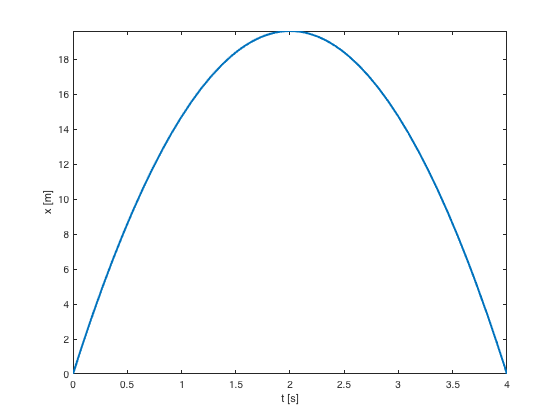

figure
fplot(x, [0, 4], 'LineWidth',2)
xlabel('t [s]'); ylabel('x [m]')

(a) The height is maximum when $\frac{\mathrm dx}{\mathrm dt}=0$

ts = solve(diff(x, t)==0, t)

$$ts = 2$$

h = double(subs(x, t, ts))

h = 19.6000

Thus the maximum height reached is $19.6\,\mathrm{m}$.

(b) Find $t$ for which $x(t)=0$

ts = solve(x == 0, t)

$$ts = \left(\begin{array}{c} 0\\ 4 \end{array}\right)$$

The required time to return is $4\,\mathrm s$.

### Electric Circuits

A simple electric circuit may consist of

- a *battery *or *generator *supplying an *electromotive force *or *e.m.f. (voltage *or *potential) *of $E$* volts,*

- a *resistor *having a *resistance *of $R$* ohms,*

- an *inductor *having an *inductance *of $L$* henries,*

- a *capacitor *or *condenser *having a *capacitance *of $C$* farads. *

The *current *$I$ measured in *amperes *is the instantaneous time rate of change of charge $Q$ on the condenser measured in *coulombs, *i.e. $I=\frac{\mathrm dQ}{\mathrm dt}$*.*

From basic principles of electricity we have

- Potential drop across resistor = $IR$

- Potential drop across inductor = $L\frac{\mathrm dI}{\mathrm dt}$

- Potential drop across capacitor = $\frac{Q}{C}$

**        Kirchhoff's Laws.**

- The algebraic sum of the currents flowing into a junction point is zero.

- The algebraic sum of the potential drops around a closed loop is zero. 

For single loop circuits the first law implies that the current is the same throughout the loop.

        **Example 21.** A resistor of $R=10\,\mathrm{\Omega}$, an inductor of $L = 2\,\mathrm H$ and a battery of $E$volts are connected in series with a switch S. At $t = 0$ the switch is closed and the current $I = 0\,\mathrm A$. Find $I$ for $t>0$ if (a) $E=40$,  (b) $E=20\mathrm e^{-3t}$, (c) $E = 50\sin5t$.

By Kirchhoff's laws,

$10I+2\frac{\mathrm dI}{\mathrm dt}+(-E)=0$ or $\frac{\mathrm dI}{\mathrm dt}+5I=\frac{E}{2}$

(a) If $E=40$, $\frac{\mathrm dI}{\mathrm dt}+5I=20$, a separable equation. Solving this subject to $I=0$ at $t=0$, we have

clear
syms t I c real
int(1/(20-5*I), I)==int(1, t)+c

$$ans = -\frac{\log\left(\text{I}-4\right)}{5}=c+t$$

eq = -log(4-I)/5==c+t;
cs = solve(subs(eq, [t, I], [0, 0]), c);
eq = subs(eq, c, cs);
eq = simplify(exp(lhs(eq))) == simplify(exp(rhs(eq)));
solve(eq, I)

$$ans = 4-4\,{\mathrm{e}}^{-5\,t}$$

(b) If $E=20\mathrm e^{-3t}$, $\frac{\mathrm dI}{\mathrm dt}+5I=10\mathrm e^{-3t}$, a linear equation. Solving this subject to $I=0$ at $t=0$, yields

clear
syms t real
P = 5;
Q = 10*exp(-3*t);
mu = exp(int(P, t));
syms I c real
eq = 1/mu*int(Q*mu, t)+c/mu;
cs = solve(subs(eq==0, [t, I], [0, 0]), c);
subs(eq, c, cs)

$$ans = 5\,{\mathrm{e}}^{-3\,t}-5\,{\mathrm{e}}^{-5\,t}$$

(c) If $E = 50\sin5t$, $\frac{\mathrm dI}{\mathrm dt}+5I=25\sin5t$, a linear equation. Solving this subject to $I=0$ at $t=0$, yields

clear
syms t real
P = 5;
Q = 25*sin(5*t);
mu = exp(int(P, t));
syms I c real
eq = 1/mu*int(Q*mu, t)+c/mu;
cs = solve(subs(I==eq, [t, I], [0, 0]), c);
I = subs(eq, c, cs)

$$I = \frac{5\,{\mathrm{e}}^{-5\,t}}{2}-\frac{5\,\cos\left(5\,t\right)}{2}+\frac{5\,\sin\left(5\,t\right)}{2}$$

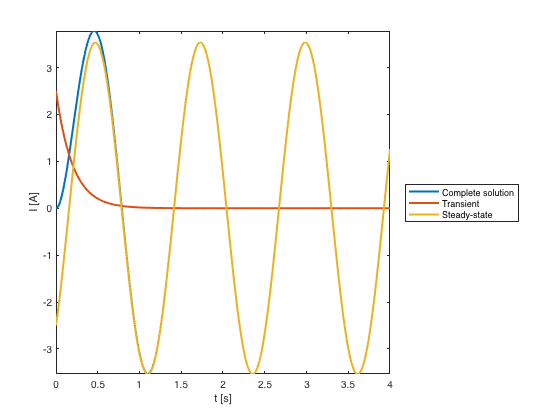

figure
fplot(I, [0, 4], 'LineWidth', 2)
xlabel('t [s]'); ylabel('I [A]')
hold on
fplot(5*exp(-5*t)/2, [0,4], 'LineWidth', 2)
fplot(5/2*(sin(5*t)-cos(5*t)), [0,4], 'LineWidth', 2)
legend({'Complete solution', 'Transient', 'Steady-state'}, "Location", "eastoutside")					

The term $\frac{1}{2}\mathrm e^{-5t}$, which approaches zero as *t *increases, is called the *transient *current. The remaining terms $\frac{1}{2}(\sin 5t-\cos 5t)$ comprise the *steady-state *current. 

### Orthogonal Trajectories

A curve cutting each member of a one parameter family of curves at right angles is called an *orthogonal trajectory *of the family. If *dy/dx = F(x, y) *is the differential equation of a one parameter family (not containing the parameter), then the differential equation for the family of orthogonal trajectories is


$$\frac{\mathrm dy}{\mathrm dx}=-\frac{1}{F(x,y)}$$


        **Example 22.** (a) Find the orthogonal trajectories of the family of curves $y=cx^2$ and (b) give a geometrical interpretation.

(a) The differential equation of the family is

clear
syms c x y real
f = c*x^2;
Dy = diff(f, x);
cs = solve(y == f, c);
Dy = subs(Dy, c, cs)

$$Dy = \frac{2\,y}{x}$$

Since the slope of each member of the orthogonal family must be the negative reciprocal of this slope, we see that the slope of the orthogonal family is


$$\frac{\mathrm dy}{\mathrm dx}=-\frac{x}{2y$$


Solving this

syms k
eq = int(x, x) + int(2*y, y) + k

$$eq = \frac{x^{2}}{2}+y^{2}+k$$

 (b) The family $y=cx^2$ is a family of parabolas whole the orthogonal family $x^2+2y^2=k$ is a family of ellipses.

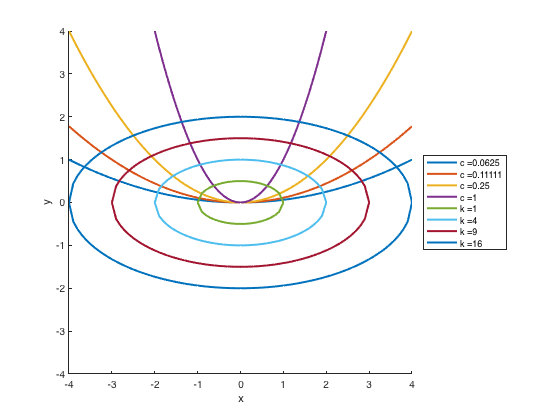

clear
figure
hold on
x = -4:0.1:4;
legends = {};
for c = [1/16, 1/9, 1/4, 1] 
    plot(x, c*x.^2, "LineWidth", 2)
    legends{end+1} = strcat('c = ', num2str(c));
end
for k = [1, 4, 9, 16]
    x = -sqrt(k):0.1:sqrt(k);
    y = 0.5*sqrt(k-x.^2);
    x = [x, x(end:-1:1)];
    y = [y, -y];
    plot(x, y, "LineWidth", 2)
    legends{end+1} = strcat('k = ', num2str(k));
end
axis equal
axis([-4 4 -4 4])
legend(legends, 'Location', 'eastoutside')
xlabel('x'); ylabel('y')

### Deflection of Beams

A horizontal beam situated on the $x$ axis of an $xy$ coordinate system and supported in various ways, bends under the influence of vertical loads. The *delection curve *of the beam, often called the *elastic curve*, is given by $y = f(x)$ where $y$ is measured as positive downward. This curve may be determined from the equation


$$\frac{EIy\prime\prime}{\left(1+y\prime^2\right)^\frac{3}{2}}=M(x)$$


where $M(x)$ is the *bending moment *at $x$ and is equal to the algebraic sum of the moments of all forces to one side of *x, *the moments being taken as positive for forces in the positive *y *direction and negative otherwise. 		

For small deflections $y\prime$ is small and the approximate equation


$$EIy\prime\prime=M(x)$$
 

is used. The quantity $EI$ where $E$ is *Young's modulus *and $I$ is the moment of inertia of a cross section of the beam about its central axis, is called the *flexural rigidity *and is generally constant. 

        **Example 23.** A beam of length $L$ is simply supported at both ends. (a) Find the deflection if the beam has constant weight $W$ per unit length and (b) determine the maximum deflection.

(a) The total weight of the beam is $WL$, so each end supports weight $\frac{1}{2}WL$. Let $x$ be the distance from the left end of the beam. To find the bending moment $M$ at $x$, consider forces to the left of $x$. 

- Force $\frac{1}{2}WL$ at the left end has moment $-\left(\frac{1}{2}WL\right)x$.

- Force due to weight of beam to left of x has magnitude Wx and moment


$$Wx\left(\frac{x}{2}\right)=\frac{1}{2}Wx^2$$


Then the total bending moment at $x$ is $\frac{1}{2}Wx^2-\frac{1}{2}WLx$. Thus


$$EIy\prime\prime=\frac{1}{2}Wx^2-\frac{1}{2}WLx$$


Solving this subject to $y=0$ at $x=0$ and $x=L$.

clear
syms x c1 c2 EI real
syms W L positive
y = int(int(1/(2*EI)*(W*x^2-W*L*x), x) + c1, x) + c2

$$y = c_{2}+c_{1}\,x+\frac{x\,\left(W\,x^{3}-2\,L\,W\,x^{2}\right)}{24\,\mathrm{EI}}$$

sol = solve(subs(y, x, 0)==0, subs(y, x, L)==0, c1, c2);
y = simplify(subs(y, [c1, c2], [sol.c1, sol.c2]))

$$y = \frac{W\,x\,\left(L^{3}-2\,L\,x^{2}+x^{3}\right)}{24\,\mathrm{EI}}$$

(b) The maximum deflection occurs at

xs = solve(diff(y, x)==0, x)

$$xs = \left(\begin{array}{c} \frac{L}{2}-\frac{\sqrt{3}\,L}{2}\\ \frac{L}{2}+\frac{\sqrt{3}\,L}{2}\\ \frac{L}{2} \end{array}\right)$$

xs = solve(diff(y, x)==0, x>0, x<L, x)

$$xs = \frac{L}{2}$$

subs(y, x, xs)

$$ans = \frac{5\,L^{4}\,W}{384\,\mathrm{EI}}$$

### Miscellaneous Problems

Various problems of science and engineering pertaining to temperature, heat flow, chemistry, radioactivity, etc., can be mathematically formulated in terms of differential equations. 

        **Example 24.** Newton's law of cooling states that the time rate of change in temperature of an object varies as the difference in temperature between object and surroundings. If an object cools from 80°C to 60°C in 20 minutes, find the temperature in 40 minutes if the surrounding temperature is 20°C.

Let $T(t)$ the temperature after $t$ minutes. Then


$$\frac{\mathrm dT}{\mathrm dt}=k(T-20)$$


Solving

clear
syms t T k c
eq =  int(1/(T-20), T) == int(k, t) + c;
eq = exp(lhs(eq)) == exp(rhs(eq))

$$eq = T-20={\mathrm{e}}^{c+k\,t}$$

At $t=0$, $T=80$ and at $t=20$, $T=60$. Then

sol = solve(subs(eq, [t, T], [0, 80]), subs(eq, [t, T], [20, 60]), k, c);
sol.k

$$ans = \log\left(\frac{2^{1/20}\,3^{19/20}}{3}\right)$$

eq = (subs(eq+20, [k, c], [sol.k, sol.c]))

$$eq = T={\mathrm{e}}^{\log\left(60\right)+t\,\log\left(\frac{2^{1/20}\,3^{19/20}}{3}\right)}+20$$

double(rhs(subs(eq, t, 40)))

ans = 46.6667

## The Matlab function `dsolve`

***Can not be used to solve a differential equation during a test or exam!***

### General Solutions

`S =` `dsolve``(eqn)` solves the differential equation `eqn`, where `eqn` is a symbolic equation. Use `diff` and `==` to represent differential equations. For example, `diff(y,x) == y` represents the equation $\frac{\mathrm dy}{\mathrm dx}$.

        **Example 25.** Solve the first-order differential equation $\frac{\mathrm dy}{\mathrm dx}=ay$.

clear
syms y(x) a
eqn = diff(y,x) == a*y;
dsolve(eqn)

$$ans = C_{1}\,{\mathrm{e}}^{a\,x}$$

        **Example 26.** Solve the second-order differential equation $\frac{\mathrm d^2y}{\mathrm dx^2}=ay$.

clear
syms y(x) a
eqn = diff(y,x,2) == a*y;
dsolve(eqn)

$$ans = C_{1}\,{\mathrm{e}}^{-\sqrt{a}\,x}+C_{2}\,{\mathrm{e}}^{\sqrt{a}\,x}$$

### Particular Solutions

`S ``=` `dsolve``(eqn,cond)` solves `eqn` with the initial or boundary condition `cond`.

        **Example 27.** Solve the first-order differential equation $\frac{\mathrm dy}{\mathrm dx}=ay$ with the initial condition $y(0)=5$.

clear
syms y(x) a
eqn = diff(y,x) == a*y;
cond = y(0) == 5;
dsolve(eqn,cond)

$$ans = 5\,{\mathrm{e}}^{a\,x}$$

        **Example 28.** Next, solve the second-order differential equation $\frac{\mathrm d^2y}{\mathrm dx^2}=ay$ with the initial conditions $y(0)=b$ and $y\prime(0)=1$.

clear
syms y(x) a b
eqn = diff(y,x,2) == a^2*y;
Dy = diff(y,x);
cond = [y(0)==b, Dy(0)==1];
dsolve(eqn,cond)

$$ans = \frac{{\mathrm{e}}^{a\,x}\,\left(a\,b+1\right)}{2\,a}+\frac{{\mathrm{e}}^{-a\,x}\,\left(a\,b-1\right)}{2\,a}$$

### Implicit Solutions

If `dsolve` cannot find an explicit solution of a differential equation analytically, then it returns an empty symbolic array.

        **Example 29.** Solve $\frac{\mathrm dy}{\mathrm dx}=\frac{x-\mathrm e^{-x}}{y+\mathrm e^y}$.

clear
syms x y(x)
eqn = diff(y) == (x-exp(-x))/(y(x)+exp(y(x)));
dsolve(eqn)

 
ans =
 
[ empty sym ]
 


You can try finding an implicit solution of the differential equation by specifying the `'Implicit'` option to `true`.

dsolve(eqn,'Implicit',true)

$$ans = {\mathrm{e}}^{y\left(x\right)}+\frac{{y\left(x\right)}^{2}}{2}=C_{1}+{\mathrm{e}}^{-x}+\frac{x^{2}}{2}$$